## **Driver test program to check Clothoids library**

**Clothods list**

Test algorithm from the publication:

- E. Bertolazzi, M. Frego, *Interpolating clothoid splines with curvature continuity,* Mathematical Methods in the Applied Sciences, 2018, vol. 41, n.4, pp. 1099-147,  https://doi.org/10.1002/mma.4700

close all;

X = [2.9265642,2.6734362,2.5109322,1.9078122,1.1859282,1.9249962, ...
     2.8265562,0.00468420000000025,-2.826567,-1.9437558,-1.1859438, ...
     -1.9062558,-2.501565,-2.6734386,-2.9265642,-2.6187522,-1.1406318, ...
     -0.8968758,-1.4562558,-1.9062558,-0.00468780000000013,1.9078122, ...
     1.4468682,0.8968722,1.1406282,2.6187522, 2.9265642 ];
Y = [-1.707808758,-1.707808758,-2.367185958,-2.582810358,-2.582810358, ...
     -1.167184758,0.915619242,3.178123242,0.915619242,-1.150000758, ...
     -2.582810358,-2.582810358,-2.393750358,-1.707808758,-1.707808758, ...
     -3.178123242,-3.178123242,-2.989063158,-0.915616758,0.925003242, ...
     2.953123242,0.925003242,-0.915616758,-2.989063158,-3.178123242,-3.178123242, -1.707808758 ];

SC = ClothoidSplineG2();
%S.ipopt(true);

subplot(3,1,1);
% build G2 spline of clothoids with target P2
S = SC.buildP2( X, Y );


                                        First-Order                    Norm of 
 Iteration  Func-count    Residual       optimality      Lambda           step
     0           1         50.1412            58.3         0.01
     1           2        0.202802            6.29        0.001        1.73487
     2           3     8.47412e-07         0.00874       0.0001      0.0619425
     3           4     1.81744e-16        1.46e-07        1e-05    0.000199672
     4           5     3.10873e-27        2.28e-13        1e-06    5.92593e-09

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

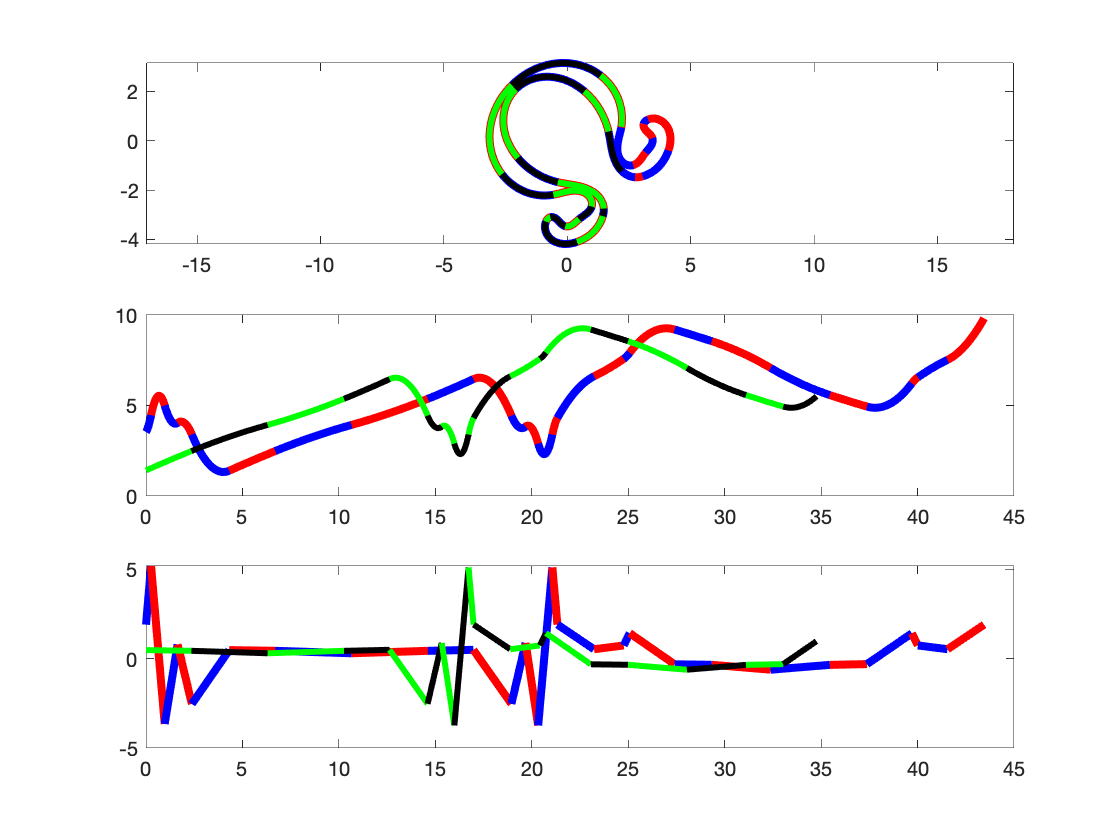

S.rotate(pi/4,0,0);
len = S.length();

fmt1 = {'Color','red','LineWidth',4};
fmt2 = {'Color','blue','LineWidth',4};
S.plot( 100, fmt1, fmt2);

S1 = ClothoidList();
S1.copy(S);

fmt3 = {'Color','black','LineWidth',3};
fmt4 = {'Color','green','LineWidth',3};
s0 = 0.1*len;
s1 = 0.9*len;
S1.trim( s0, s1 );
S1.plot( 100, fmt3, fmt4);

axis equal

subplot(3,1,2);
S.plotAngle( 100, fmt1, fmt2);
hold on;
S1.plotAngle( 100, fmt3, fmt4);

subplot(3,1,3);
S.plotCurvature( 100, fmt1, fmt2);
hold on;
S1.plotCurvature( 100, fmt3, fmt4);

ds = 0.234;
ss = [0,5];

[x1,y1,theta1,kappa1] = S.evaluate( s0+ds+ss );
[x2,y2,theta2,kappa2] = S1.evaluate( 0+ds+ss );

length(x1)

ans =      2


length(x2)

ans =      2



disp('-----------');

-----------


for k=1:length(ss)
  fprintf('x = %g y = %g theta = %g kappa = %g\n', x1(k), y1(k), theta1(k), kappa1(k) );
  fprintf('x = %g y = %g theta = %g kappa = %g\n', x2(k), y2(k), theta2(k), kappa2(k) );
  fprintf('dx = %g dy = %g dtheta = %g dkappa = %g\n', x1(k)-x2(k), y1(k)-y2(k), theta1(k)-theta2(k), kappa1(k)-kappa2(k) );
end

x = 2.21558 y = 0.799714 theta = 1.52355 kappa = 0.469257


x = 2.21558 y = 0.799714 theta = 1.52355 kappa = 0.469257


dx = 4.44089e-16 dy = 0 dtheta = 0 dkappa = 0


x = -1.3757 y = 2.86957 theta = 3.58878 kappa = 0.333858


x = -1.3757 y = 2.86957 theta = 3.58878 kappa = 0.333858


dx = 0 dy = 0 dtheta = 0 dkappa = 0



disp('-----------');

-----------



ss = [0,1,2,3,4,5];
for k=1:length(ss)
  [x1,y1,theta1,kappa1] = S.evaluate( s0+ds+ss(k) );
  [x2,y2,theta2,kappa2] = S1.evaluate( 0+ds+ss(k) );
  fprintf('x = %g y = %g theta = %g kappa = %g\n', x1, y1, theta1, kappa1 );
  fprintf('x = %g y = %g theta = %g kappa = %g\n', x2, y2, theta2, kappa2 );
  fprintf('dx = %g dy = %g dtheta = %g dkappa = %g\n', x1-x2, y1-y2, theta1-theta2, kappa1-kappa2 );
end

x = 2.21558 y = 0.799714 theta = 1.52355 kappa = 0.469257


x = 2.21558 y = 0.799714 theta = 1.52355 kappa = 0.469257


dx = 4.44089e-16 dy = 0 dtheta = 0 dkappa = 0


x = 2.03358 y = 1.77402 theta = 1.98469 kappa = 0.453023


x = 2.03358 y = 1.77402 theta = 1.98469 kappa = 0.453023


dx = -4.44089e-16 dy = 1.9984e-15 dtheta = 0 dkappa = 0


x = 1.44313 y = 2.57088 theta = 2.42959 kappa = 0.43679


x = 1.44313 y = 2.57088 theta = 2.42959 kappa = 0.43679


dx = -2.88658e-15 dy = 8.88178e-16 dtheta = 0 dkappa = 0


x = 0.571287 y = 3.04541 theta = 2.85096 kappa = 0.403969


x = 0.571287 y = 3.04541 theta = 2.85096 kappa = 0.403969


dx = 0 dy = 0 dtheta = 0 dkappa = 0


x = -0.418068 y = 3.13917 theta = 3.2374 kappa = 0.368913


x = -0.418068 y = 3.13917 theta = 3.2374 kappa = 0.368913


dx = 0 dy = 0 dtheta = 0 dkappa = 0


x = -1.3757 y = 2.86957 theta = 3.58878 kappa = 0.333858


x = -1.3757 y = 2.86957 theta = 3.58878 kappa = 0.333858


dx = 0 dy = 0 dtheta = 0 dkappa = 0
